# MATLAB basics and regression

## 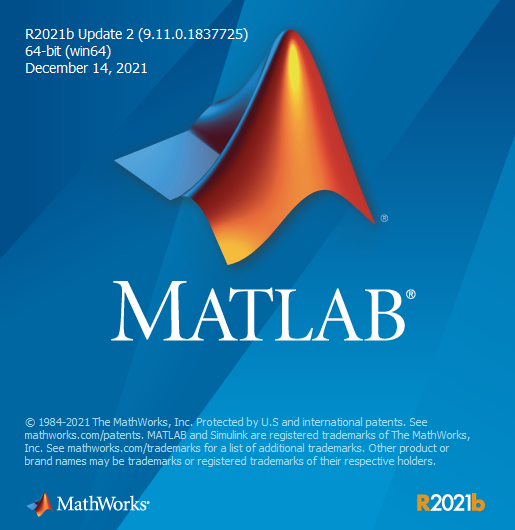

## 0. Why MATLAB?

MATLAB is a proprietary programming language and computing enviorment developed by MathWorks. It is specifically desinged for engineers and scientists who work with data matrices of large sizes. Some of its advantages over other options (e.g., R, Python) include:

- having a graphical user interface (GUI)

- (relatively) easy-to-understand data types

- comprehensive tried-and-tested built-in functions

- various toolboxes for brain research and beyond

Here are some famous/useful fMRI packages that you might use:

And here are some previous DIBS Methods Meeting posts that used MATLAB to some extent: 

- [MATLAB basics](https://dibsmethodsmeetings.github.io/matlab-basics/)

- [Multivariate pattern analysis](https://dibsmethodsmeetings.github.io/multivariate-pattern-analysis/)

- [EEG Preprocessing using EEGLAB](https://dibsmethodsmeetings.github.io/eeg-analysis/) 

- [Decomposing Fourier transforms](https://dibsmethodsmeetings.github.io/fourier-transforms/)

## 1. Getting started

Let's get started! If you haven't installed MATLAB or want to familiarize yourself with the GUI, please refer to [my earlier post on MATLAB basics](https://dibsmethodsmeetings.github.io/matlab-basics/) OR try out the online version here: [https://matlab.mathworks.com/.](https://matlab.mathworks.com)

## 2. Data types and operations

This was covered in a bit more depths in [my earlier post](https://dibsmethodsmeetings.github.io/matlab-basics/), but I thought I would do a quick review of some important things here because they are going to come up later as we talk about regression.

#### Numeric types

% double	Double-precision arrays (64-bit) <-- MATLAB default
% single	Single-precision arrays (32-bit)
% int8	    8-bit signed integer arrays
% uint8	    8-bit unsigned integer arrays
% ...
% for example:
class(1) % use the function class to check data types

ans = 'double'

% use space or comma to separate columns
% use semicolon to separate rows
% use square brackets [ ] to put things together
a = [1    2,    NaN;
    .5    Inf   nan] % this is a 2 x 3 double array

a =     1.0000    2.0000       NaN
    0.5000       Inf       NaN


% note the two special numbers: Inf and NaN (not a number)
class(a) % the data type is still 'double'

ans = 'double'

#### Characters and Strings

% use single quotes for characters
char1 = 'a';
char2 = 'abc';
% use double quotes for strings
str1 = "a";
str2 = "abc";
% check data types
class(char1);
class(str1);
% difference
length(char2)

ans = 3

length(str2)

ans = 1

% if we want to concatnate different things
[char1 char2] % correctly concatenated character array

ans = 'aabc'

str1 + str2 % correctly concatenated strings

ans = "aabc"

char1 + char2 % data type converted to numeric for addition

ans =    194   195   196


[char1 str2] % character coerced to string

ans = 1×2 string array
    "a"    "abc"


#### Tables

T = table;
T.col1 = [1; 2];
T.col2 = ["hello"; "world"];
T

T = 2×2 table
    col1     col2  
    ____    _______

     1      "hello"
     2      "world"


% dimensions must match
T.col3 = repmat(3, height(T), 1);
try T.col4 = 4; catch err; disp(err); end

  MException with properties:

    identifier: 'MATLAB:table:RowDimensionMismatch'
       message: 'To assign to or create a variable in a table, the number of rows must match the height of the table.'
         cause: {}
         stack: [2×1 struct]
    Correction: []



% data type must be consistent within each row
T.col2(2) = 1;
T % see how 1 is coerced into "1"

T = 2×3 table
    col1     col2      col3
    ____    _______    ____

     1      "hello"     3  
     2      "1"         3  


class(T.col2)

ans = 'string'

#### Cell Arrays

% use curly brackets to put together things of different sizes and types
C = {42, "abcd"; table(nan), [1 2 3]; Inf, {}}

C = 3×2 cell array
    {[     42]}    {["abcd"]}
    {1×1 table}    {[ 1 2 3]}
    {[    Inf]}    {0×0 cell}


C(2) % paratheses indexing retrieves the cell 

ans = 1×1 cell array
    {1×1 table}


C{2} % curly braces indexing retrieves the cell *content*

ans = table
    Var1
    ____

    NaN 


Arrays are effcient, but make sure you access the in the correct order.

% double arrays are indexed with parentheses
a = [11 12 13; 21 23 24]; % 2 x 3 double array
a

a =     11    12    13
    21    23    24


a(1, 2) % row 1, column 2

ans = 12

a(1:end, 2) % all rows, column 2

ans =     12
    23


a(2, :) % row 2, all columns

ans =     21    23    24


% here's something that may seem odd
a(4) % 4th entry

ans = 23

a(:) % all entries

ans =     11
    21
    12
    23
    13
    24


In Python and R, array data is stored **row-wise**. In contrast, MATLAB arrays are stored **column-wise**, even though they are easily defined row-wise. 

┑(￣Д ￣)┍ 

#### Structures

% group data using fields
% each field can be of any data type, including structures
S = struct;
S.field1_struct = struct;
S.field2_cell = C;
S.field3_table = T;
S.field4_char = char1;
S

S = struct with fields:
    field1_struct: [1×1 struct]
      field2_cell: {3×2 cell}
     field3_table: [2×3 table]
      field4_char: 'a'


## 3. Regression

Let's talk about regression! Through the official [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html), we have access to several built-in MATLAB functions for regression. 

First, let's load some data. We are going to use an [open dataset on Kaggle on life expectancy](https://www.kaggle.com/datasets/kumarajarshi/life-expectancy-who). The original data came from the World Health Organization (WHO), who has been keeping track of the life expectancy and many other health factors of all countries. The final dataset consists of 20 predictor variables and 2938 rows, containing information for 193 countries between 2000 and 2015.

data_table = readtable("2024-03-01-matlab-regression-Life-Expectancy.csv", ...
    "VariableNamingRule", "preserve"); % preserve white space in column names for readability
head(data_table);

        Country        Year        Status        Life expectancy    Adult Mortality    infant deaths    Alcohol    percentage expenditure    Hepatitis B    Measles    BMI     under-five deaths    Polio    Total expenditure    Diphtheria    HIV/AIDS     GDP      Population    thinness  1-19 years    thinness 5-9 years    Income composition of resources    Schooling
    _______________    ____    ______________    _______________    _______________    _____________    _______    _________________

Let's validate the information in the description above.

fprintf( ...
    "Number of rows = %d \n" + ...
    "Number of years = %d \n" + ...
    "Number of countries = %d \n", ...
    height(data_table), ...
    length(unique(data_table.Year)), ...
    length(unique(data_table.Country)));

Number of rows = 2938 
Number of years = 16 
Number of countries = 193 


For simplicity, we are going to focus on the most recent complete sample (year 2014) and on the following variables:

- Life expectancy (in years)

- Status: "Developed", "Developing"

- Total expenditure: General government expenditure on health as a percentage of total government expenditure (%)

data_2014 = data_table(data_table.Year==2014, ["Country" "Status" "Total expenditure" "Life expectancy"]);
head(data_2014);

            Country                Status        Total expenditure    Life expectancy
    _______________________    ______________    _________________    _______________

    {'Afghanistan'        }    {'Developing'}          8.18                59.9      
    {'Albania'            }    {'Developing'}          5.88                77.5      
    {'Algeria'            }    {'Developing'}          7.21                75.4      
    {'Angola'             }    {'Developing'}          3.31                51.7      
    {'Antigua and Barbuda'}    {'Developing'}          5.54                76.2      
    {'Argentina'          }    {'Developing'}          4.79                76.2      
    {'Armenia'            }    {'Developing'}          4.48                74.6      
    {'Australia'          }    {'Developed' }          9.42                82.7      



Before actually fitting a linear regression model, let's plot the data.

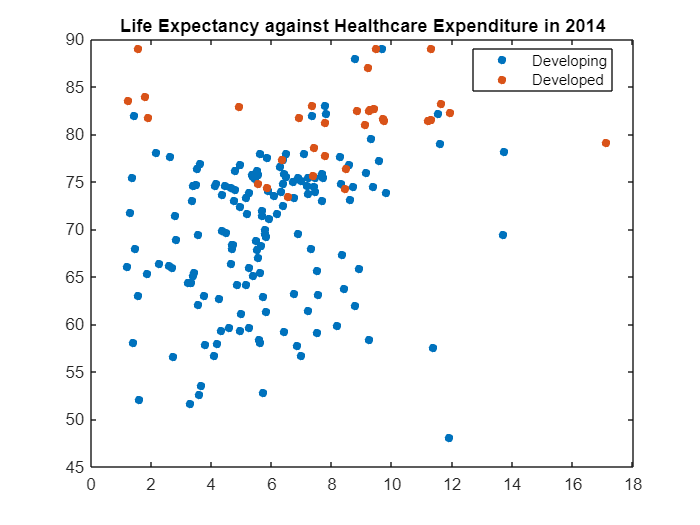

close all
figure
gscatter( ...
    data_2014.("Total expenditure"), ... x-axis
    data_2014.("Life expectancy"), ... y-axis
    data_2014.Status ... color
    );
title("Life Expectancy against Healthcare Expenditure in 2014")

We make 3 observations:

- There are much fewer developed countries (orange) than developing countries (blue). 

- Developed countries tend to have higher life expectancy than developing countries.

- Life expectance MAYBE is positively correlated with heathcare expenditure for developing countries, but less so for developed countries.

Now let's fit some linear regression models! 

We're going to use the [`fitlm`](https://www.mathworks.com/help/stats/linear-regression-model-workflow.html) function in MATLAB. This function provides very detailed outputs. 

data_2014.Status = categorical(data_2014.Status, ["Developing" "Developed"]); %%% note the order
data_2014.LE = data_2014.("Life expectancy");
data_2014.TE = data_2014.("Total expenditure");
m1 = fitlm(data_2014, "LE ~ TE * Status");
% anova(m1, "component", 3) %%% Type III anova
m1 %%% regression coefficients and stats

m1 = Linear regression model:
    LE ~ 1 + Status*TE

Estimated Coefficients:
                           Estimate      SE        tStat       pValue  
                           ________    _______    _______    __________

    (Intercept)              65.288     1.5208      42.93    1.6594e-95
    Status_Developed         15.824     3.6356     4.3525    2.2717e-05
    TE                      0.73836    0.24142     3.0584     0.0025709
    Status_Developed:TE    -0.73511    0.45121    -1.6292       0.10505


Number of observations: 181, Error degrees of freedom: 177
Root Mean Squared Error: 7.15
R-squared: 0.307,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 26.1, p-value = 5.11e-14

Note that it's critically important to know how to correctly interpret these results, e.g., what is the "Intercept" and whether "TE" is a simple effect or a main effect. See more in [Kevin's post on *Interpreting Regression Coefficients*](https://dibsmethodsmeetings.github.io/contrasts/). Briefly, the order of the categorical variable AND whether the continuous variable is mean-centered matters. Let's see:

data_2014.Status_rev = categorical(data_2014.Status, ["Developed" "Developing"]);
data_2014.TE_mc = data_2014.TE - mean(data_2014.TE, "omitmissing");
m2 = fitlm(data_2014, "LE ~ TE_mc * Status");
m3 = fitlm(data_2014, "LE ~ TE_mc * Status_rev");
m1.Coefficients

ans = 4×4 table
                           Estimate      SE        tStat       pValue  
                           ________    _______    _______    __________

    (Intercept)              65.288     1.5208      42.93    1.6594e-95
    Status_Developed         15.824     3.6356     4.3525    2.2717e-05
    TE                      0.73836    0.24142     3.0584     0.0025709
    Status_Developed:TE    -0.73511    0.45121    -1.6292       0.10505


m2.Coefficients

ans = 4×4 table
                              Estimate      SE        tStat       pValue   
                              ________    _______    _______    ___________

    (Intercept)                 69.866    0.59293     117.83    4.2208e-170
    Status_Developed            11.265     1.5557     7.2414     1.3086e-11
    TE_mc                      0.73836    0.24142     3.0584      0.0025709
    Status_Developed:TE_mc    -0.73511    0.45121    -1.6292        0.10505


m3.Coefficients

ans = 4×4 table
                                   Estimate      SE         tStat        pValue   
                                   ________    _______    _________    ___________

    (Intercept)                      81.132     1.4382        56.41    4.6108e-115
    Status_rev_Developing           -11.265     1.5557      -7.2414     1.3086e-11
    TE_mc                          0.003247    0.38119    0.0085182        0.99321
    Status_rev_Developing:TE_mc     0.73511    0.45121       1.6292        0.10505


Let's quickly plot the effects of TE (with 95% confidence intervals) on LE, separately for developed and developing countries. This is essentially doing `plot(ggemmeans(m, ~ TE + Status))` in R.

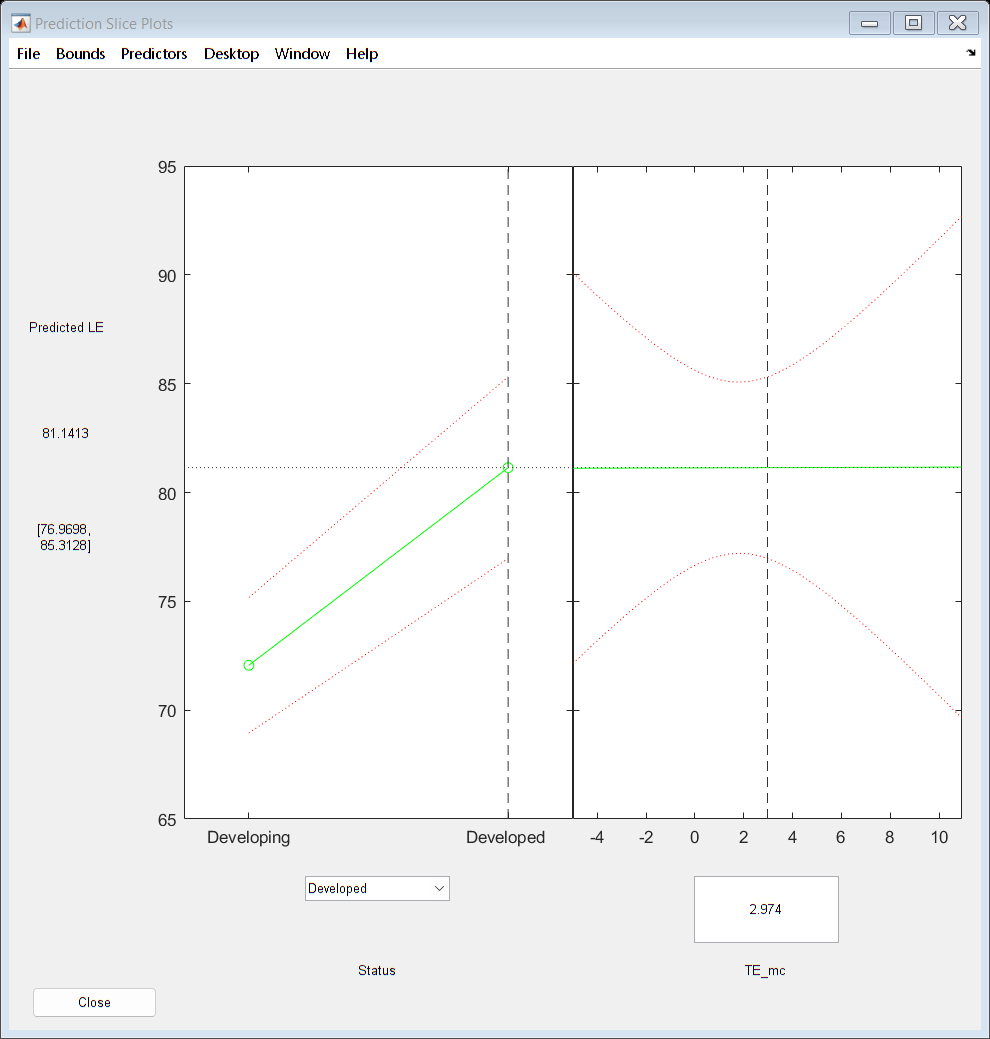

plotSlice(m2); %%% alternative syntax: `m2.plotSlice;` 

However, If we need to fit a large number of models and don't really need detailed statistics from each model, we can use the [`regress`](https://www.mathworks.com/help/stats/regress.html) function to trade comprehensiveness for speed. 

% define outcome variable
y = data_2014.LE;
% define predictor variables
X = nan(length(y), 4); %%% initialize 3 columns
X(:, 1) = 1; %%% constant term is NOT automatically put into the model!
X(:, 2) = double(data_2014.Status=="Developing"); %%% manually code the categorical variable
X(:, 3) = data_2014.("Total expenditure") - mean(data_2014.("Total expenditure"), "omitmissing");
X(:, 4) = X(:, 2) .* X(:, 3); %%% interaction term
[b, bint, r, rint, stats] = regress(y, X);
b

b =    81.1316
  -11.2652
    0.0032
    0.7351


m3.Coefficients

ans = 4×4 table
                                   Estimate      SE         tStat        pValue   
                                   ________    _______    _________    ___________

    (Intercept)                      81.132     1.4382        56.41    4.6108e-115
    Status_rev_Developing           -11.265     1.5557      -7.2414     1.3086e-11
    TE_mc                          0.003247    0.38119    0.0085182        0.99321
    Status_rev_Developing:TE_mc     0.73511    0.45121       1.6292        0.10505


all(m3.Coefficients.Estimate == b)

ans = logical
   1


Ta-da! As we can see the regression coefficients we obtained using `regress` are exactly the same as what we had from `fitlm` earlier, though we no longer have the nice-looking table filled with stats. However, the (very crude) test below shows that `regress` is indeed a lot faster than `fitlm`.

tic
for i=1:500
    y = data_2014.LE;
    % define predictor variables
    X = nan(length(y), 4); %%% initialize 3 columns
    X(:, 1) = 1; %%% constant term is NOT automatically put into the model!
    X(:, 2) = double(data_2014.Status=="Developing"); %%% manually code the categorical variable
    X(:, 3) = data_2014.("Total expenditure") - mean(data_2014.("Total expenditure"), "omitmissing");
    X(:, 4) = X(:, 2) .* X(:, 3); %%% interaction term
    [b, bint, r, rint, stats] = regress(y, X);
end
toc

Elapsed time is 0.205371 seconds.


tic
for i=1:500
    m = fitlm(data_2014, "LE ~ TE_mc * Status_rev");
end
toc

Elapsed time is 5.004565 seconds.


## 4. Conclusion

We've made it to the end of MATLAB basics and regression (yay!), though this is just the tip of the iceberge of regression models out in the wild world, such as regularized regression, nonlinear regression, and mixed-effects regression. Feel free to check out how they are can be implemented in MATLAB [here](https://www.mathworks.com/help/stats/introduction-to-parametric-regression-analysis.html). 

Enjoying MATLAB-ing!